# Hunt for a sensible LQI solution - part 1

Load the Linearised quadcopter+pendulum model

load('bh_SAVED_LIN_PLANT.mat')


**Discretize** the plant model

my_LIN_PLANT = c2d(my_LIN_PLANT,1/500);

size(my_LIN_PLANT)

State-space model with 3 outputs, 4 inputs, and 18 states.


## Control design:

We'll use the approach described by the LQI() function, ie::

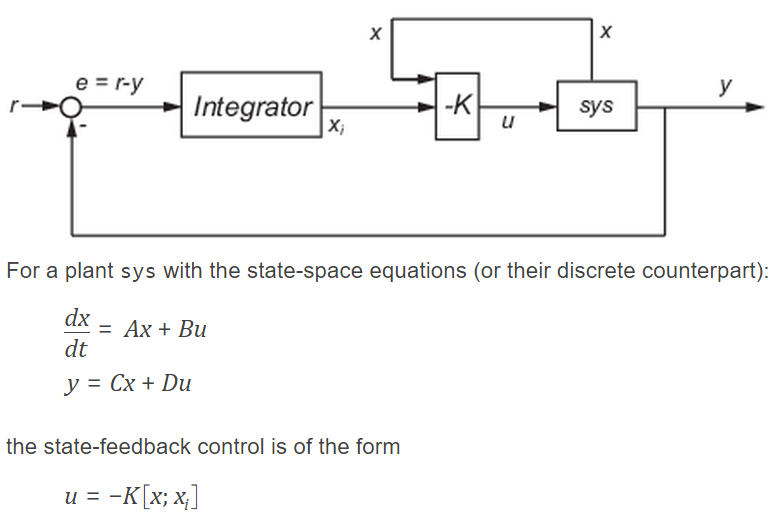

Note that:  

- 
$$K\in R^{N_u \times \left(N_x +N_y \right)}$$


A = my_LIN_PLANT.A;
B = my_LIN_PLANT.B;
C = my_LIN_PLANT.C;

Nx = size(A,1);  Nu = size(B,2);  Ny = size(C,1);

Now design a full state feedback controller using `LQI()`. NOTE the following:

- you will need to experiment with the Q,R weighting matrices

res_T.tf_is_good   = false;
res_T.K            = [];
res_T.p            = [];
res_T.tf_all_inside_unit = false;
res_T.p_first      = 0;
res_T.K_av         = 0;
res_T.g_Q          = 0;
res_T.g_R          = 0;

gg_list = 1:5e5;
res_array   = repmat(res_T, [1,length(gg_list)]);
%dt=1/500;

g_Q = 1; %0.4;

for gg=1:length(gg_list)
   try
       gg_VALUE   = gg_list(gg);
       [K, p_lqi] = LOC_do_LQI(my_LIN_PLANT, g_Q, gg_VALUE, Nx, Ny, Nu);
       res_array(gg).tf_is_good = true;
       res_array(gg).K = K;
       res_array(gg).p = p_lqi;
       if( all( abs(p_lqi) <= 1 ))
           res_array(gg).tf_all_inside_unit = true;           
       end
       res_array(gg).p_first = p_lqi(1);
       
       res_array(gg).K_av = mean(abs(K), 'all');
       res_array(gg).g_Q  = g_Q;
       res_array(gg).g_R  = gg_VALUE;       
       
       %fprintf('\n .. got one !')
   catch
       
   end
   
end % for

nnz([ res_array.tf_is_good])


Save the results to a MAT file

save('bh_results_HUNT_part_1.mat', 'res_array')

And we're done

fprintf('\n ... we are finished here @ <%s> ! \n', datestr(now) );

# Local Subfunctions only beyond this point

1                 2                        3                        4                    5                6                        7                            8                        9                            10

DOT_phi     DOT_theta       DOT_psi        DOT_Xe        DOT_Ye        DOT_Ze     DOT_phi_pend      DOT_theta_pe     DOT_psi_pend           phi

11               12            13            14                15        16            17                    18

theta           psi            Xe            Ye            Ze      phi_pend    theta_pend      psi_pend

function [K, p_lqi] = LOC_do_LQI(my_LIN_PLANT, g_Q, g_R, Nx, Ny, Nu)

%     ------------------------------------
%     tmp        = g_Q*[ones(1, Nx+Ny)];
%     tmp(19:21) = [0.6,0.6,1400];
%     Q = diag(tmp); 
%     tmp = g_R*[1,1,1,1];  %18b
%     R = diag(tmp); 
%     -----------------------------------
   
    tmp        = g_Q*[ones(1, Nx+Ny)];
    tmp(19:21) = [1 ,1,1000];
    Q = diag(tmp); 
    tmp = g_R*[1,1,1,1];  %18b
    R = diag(tmp); 

%     tmp        = g_Q*[ones(1, Nx+Ny)];
%     tmp(19:21) =     [100,100,1000];
%     tmp([11,12,13,14,15]) = [100,100,100,100,1000];
%     Q = diag(tmp);     
%     tmp  = g_R*[1,1,1,1]; % 19b - LQI uses icare() ... NEW SIMPLICIT SOLVER rolled out in 19a
%     R = diag(tmp); 


    [K,~,~] = lqi(my_LIN_PLANT,Q,R,[]);
   
    A = my_LIN_PLANT.A;
    B = my_LIN_PLANT.B;
    C = my_LIN_PLANT.C;
    
    A_hat = [  A,   zeros(Nx,Ny);
              -C,   zeros(Ny,Ny) ];
      
    B_hat = [ B;
              zeros(Ny,Nu) ];
          
    p_lqi = dsort( pole( ss((A_hat-B_hat*K),[],[],[]) ) );
    
end